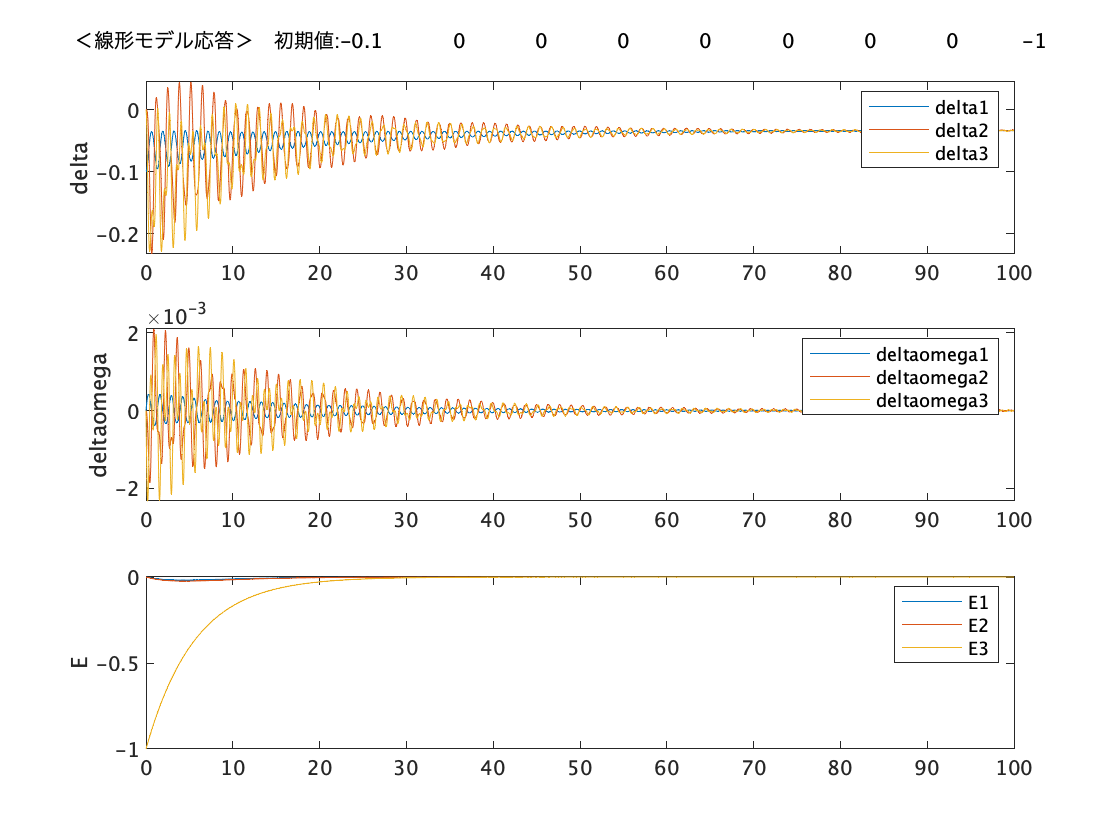

last =    -0.0338   -0.0329   -0.0335    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000


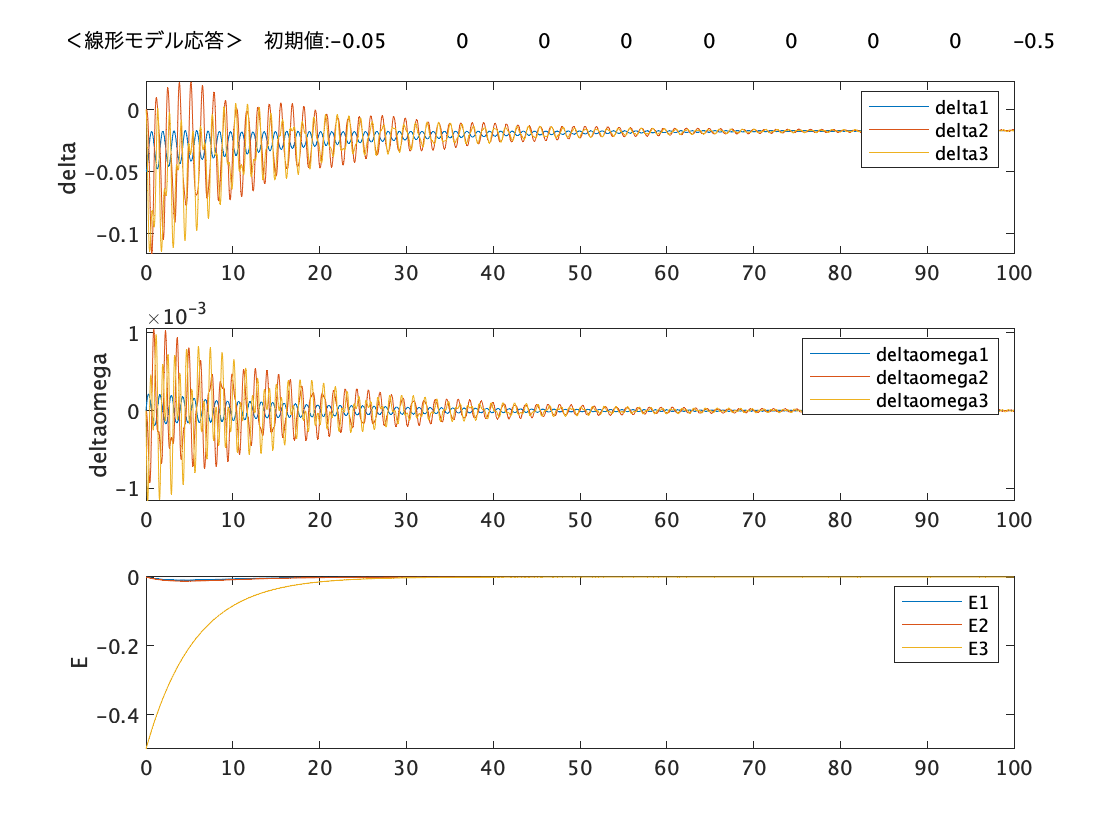

last =    -0.0169   -0.0164   -0.0168    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000


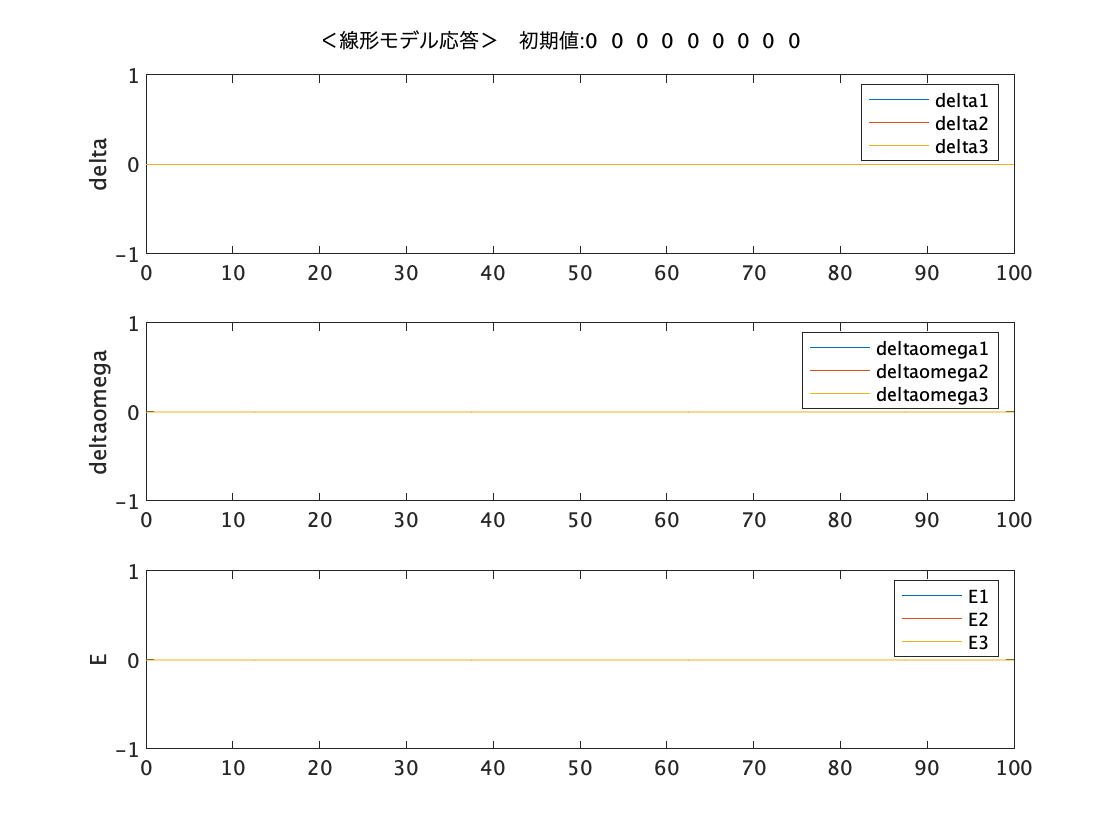

last =      0     0     0     0     0     0     0     0     0


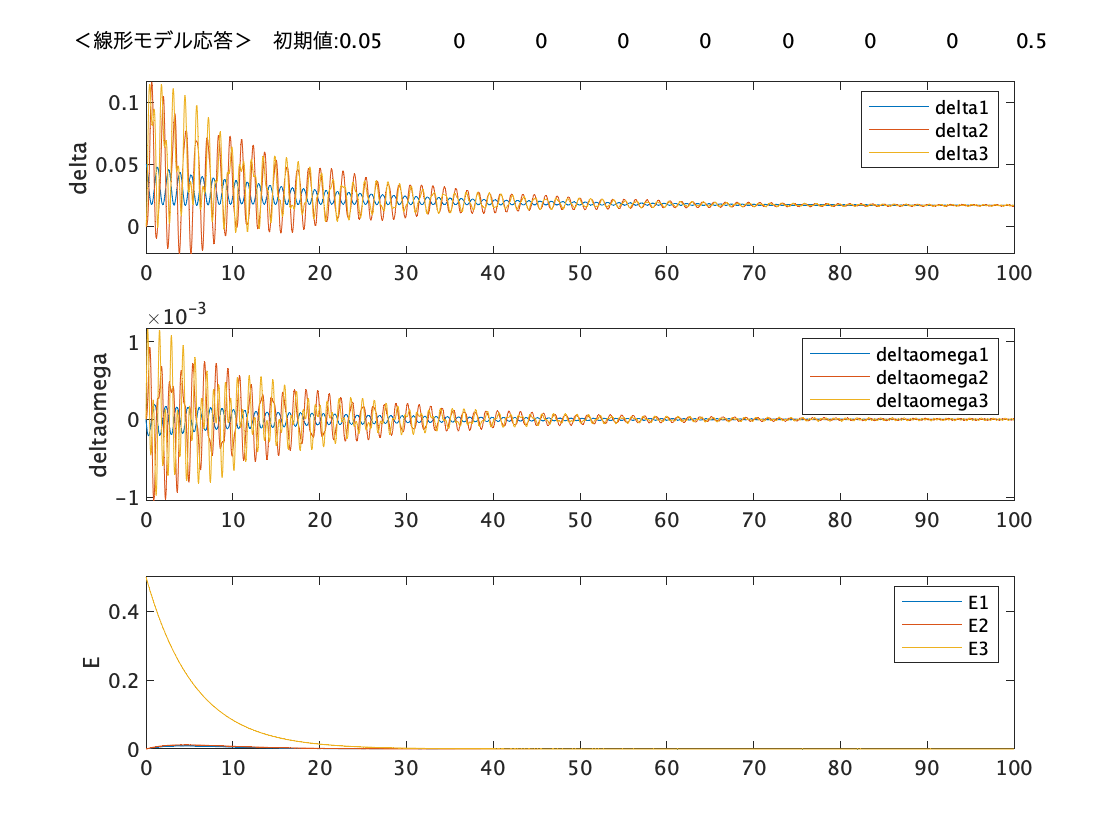

last =     0.0169    0.0164    0.0168   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000


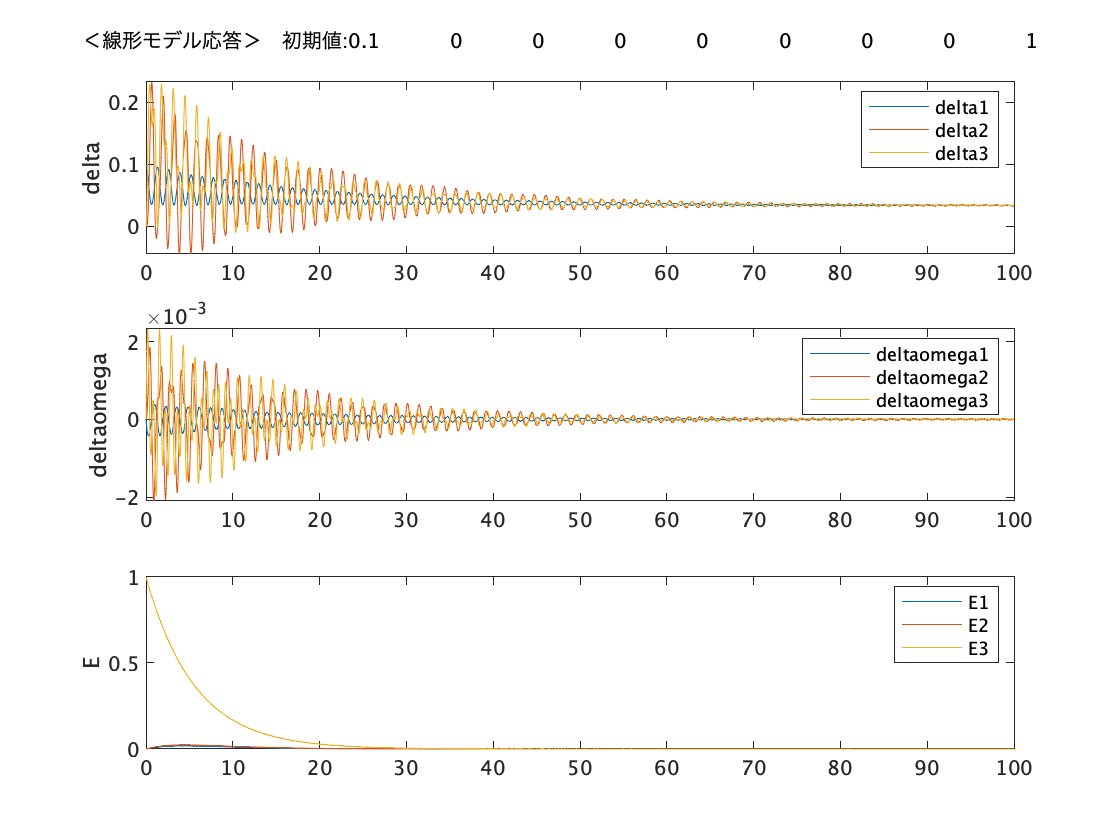

last =     0.0338    0.0329    0.0335   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000


clear

tspan = [0 100];

%平衡点を設定
steady_delta = [0.15708;0;-0.15708];
steady_deltaomega = [0;0;0];
steady_E = [3.2225;3.2225;3.2225];
steady_generator_state = [steady_delta; steady_deltaomega; steady_E];

psi = get_psi(steady_generator_state);
for cnt = -1:0.5:1
    error = [0.1;0;0;0;0;0;0;0;1]*cnt;
    figure;
    %最終値を表示
    last = plot_generator_state_linear(error,tspan,psi)
end